Connect to ROS Master

clear
rosshutdown()

Shutting down global node /matlab_global_node_76162 with NodeURI http://192.168.86.148:49748/


prompt = "ipaddress: ";
ipaddress = input(prompt, "s");
rosinit(ipaddress, 11311)

Initializing global node /matlab_global_node_23607 with NodeURI http://192.168.86.148:55433/


Create ROS subscribers

sub.scan = rossubscriber("/scan");
sub.map = rossubscriber("/map","nav_msgs/OccupancyGrid","DataFormat","struct");
sub.coverageMap = rossubscriber("/coverage_map","nav_msgs/OccupancyGrid","DataFormat","struct");
sub.amcl = rossubscriber("/amcl_pose","geometry_msgs/PoseWithCovarianceStamped","DataFormat","struct");
sub.initialpose = rossubscriber("/initialpose","geometry_msgs/PoseWithCovarianceStamped","DataFormat","struct");


Create ROS publishers

pub.goal = rospublisher("/move_base_simple/goal","geometry_msgs/PoseStamped","DataFormat","struct");
pub.map = rospublisher("/coverage_map","nav_msgs/OccupancyGrid","DataFormat","struct");

Read and display original global map published to ROS

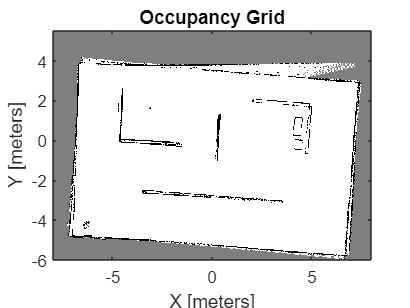

msg.map = sub.map.LatestMessage;
map = rosReadOccupancyGrid(msg.map);
show(map);

Acquire initial pose of the robot (2d pose estimate)

msg.initialpose = receive(sub.initialpose);
pos = msg.initialpose.Pose.Pose.Position;
position.initial = [pos.X, pos.Y];
position.current = position.initial;
position.current_grid_index = world2grid(map,position.current);

Republish map to '/coverage_map' topic ***(optional)***

map_msgType = rosmessage("nav_msgs/OccupancyGrid","DataFormat","struct");
map_msg = rosWriteOccupancyGrid(map_msgType,map);
send(pub.map,map_msg)
pause(0.0002)

Pre-coverage initialization

- Read coverage map from '/coverage_map' topic, 

- Initialize neural network matrix

- Update map to mark initial position as covered 

- Re-publish map. 

msg.coverageMap = sub.coverageMap.LatestMessage;
map_coverage = rosReadOccupancyGrid(msg.coverageMap);

nn_mat = zeros(map_coverage.GridSize(1), map_coverage.GridSize(2));

mapUpdate(map_coverage, position.current_grid_index) 

map_msg = rosWriteOccupancyGrid(map_msgType,map_coverage);
send(pub.map,map_msg)
pause(0.0002)

 Acquire and transform current lidar scans to map frame 

tftree = rostf;
pause(1);
searching = 0; 
incomplete = 1; 

while incomplete == 1

cartScanDataTransformed = laserScanTransform (tftree,sub.scan);

cartScanDataTransformed =     0.0374   -2.6835
    0.0479   -2.6905
    0.0587   -2.6774
    0.0693   -2.6864
    0.0800   -2.6980
    0.0907   -2.6961
    0.1012   -2.6782
    0.1122   -2.7094
    0.1228   -2.6994
    0.1335   -2.6975


cartScanDataTransformed =    -1.7646    3.4023
   -1.7849    3.4042
   -1.8026    3.3992
   -1.8267    3.4103
   -1.8436    3.4029
   -1.8643    3.4051
   -1.8864    3.4104
   -1.9038    3.4041
   -1.9262    3.4096
   -1.9543    3.4278


cartScanDataTransformed =    -0.5768    3.4408
   -0.5931    3.4396
   -0.6094    3.4351
   -0.6250    3.4456
   -0.6407    3.4553
   -0.6571    3.4508
   -0.6733    3.4493
   -0.6905    3.4196
   -0.7061    3.4348
   -0.7220    3.4417


cartScanDataTransformed =    -1.1091    3.4787
   -1.1251    3.4668
   -1.1412    3.4678
   -1.1571    3.4590
   -1.1730    3.4497
   -1.1891    3.4607
   -1.2051    3.4619
   -1.2211    3.4600
   -1.2373    3.4654
   -1.2537    3.4774


cartScanDataTransformed =    -1.5623   -0.3905
   -1.5664   -0.3892
   -1.5706   -0.3880
   -1.5784   -0.3845
   -1.5721   -0.3904
   -1.5771   -0.3887
   -1.5931   -0.3799
   -1.5740   -0.3942
   -1.5823   -0.3904
   -1.5744   -0.3972


cartScanDataTransformed =    -1.7464   -2.7302
   -1.7355   -2.7277
   -1.7243   -2.7240
   -1.7160   -2.7309
   -1.7027   -2.7190
   -1.6926   -2.7189
   -1.6813   -2.7142
   -1.6754   -2.7299
   -1.6589   -2.7046
   -1.6520   -2.7167


cartScanDataTransformed =    -2.9898   -2.3020
   -2.9755   -2.3049
   -2.9713   -2.3175
   -2.9348   -2.2982
   -2.9313   -2.3114
   -2.9151   -2.3118
   -2.8831   -2.2961
   -2.8840   -2.3137
   -2.8635   -2.3093
   -2.8608   -2.3233


Read updated coverage map from '/coverage_map' topic

msg.coverageMap = sub.coverageMap.LatestMessage;
map_coverage = rosReadOccupancyGrid(msg.coverageMap);
show(map_coverage)

Plan next movement in when in deadlock 

- Pass in current grid index position

- Overlay transformed lidar scans on deadlock map

- Calculate and publish next goal pose using PRM

- Check if robot has reached goal pose using amcl localization

- Update current grid index position

if searching > 15
    [searching, position.current_grid_index] = deadlockEvent(map_coverage,position.current_grid_index,nn_mat,sub.map,cartScanDataTransformed,pub.goal,sub.amcl)

Plan next movement for complete coverage

- Pass in current grid index position

- Overlay transformed lidar scans on coverage map

- Calculate and publish next goal pose using BINN

- Check if robot has reached goal pose using amcl localization

- Update current grid index position and 

else
    [position.next_grid_index, orientation, deadlock, nn_mat] = nextPosition(msg.coverageMap, position.current_grid_index, nn_mat, cartScanDataTransformed);
    searching = searching + deadlock;
    goal = sendPose(map_coverage, position.next_grid_index, orientation);
    send(pub.goal,goal);
    position.current_grid_index = arrived(map_coverage, position.next_grid_index, sub.amcl);
end

Update and re-publish map

mapUpdate(map_coverage, position.current_grid_index) 

map_msg = rosWriteOccupancyGrid(map_msgType,map_coverage);
send(pub.map,map_msg)
pause(0.0002)

Stop condition to check if map/environment is completely covered 

if sum(nn_mat>=0.5, 'all') == 0
    incomplete = 0;
end 

end